# **Lab 2 (Sunspot Activity)**

**by Jason Ha (z5115925)**

In this lab, we investigate the trend in sunspot data over time since the year of 1818. We expect to visualise a time-series that we can treat equally as a signal and perform the the usual transformations such as Fourier Transforms and more. 

## Step 1 - Importing The Data

% Use the function 'readtable' to read the CSV file into the workspace
% Assign the loaded dataset to the variable 'raw'
raw = readtable("SN_d_tot_V2.0.csv")

raw = 72743×8 table
    Var1    Var2    Var3    Var4    Var5    Var6    Var7    Var8
    ____    ____    ____    ____    ____    ____    ____    ____

    1818     1        1     1818     -1       -1     0       1  
    1818     1        2     1818     -1       -1     0       1  
    1818     1        3     1818     -1       -1     0       1  
    1818     1        4     1818     -1       -1     0       1  
    1818     1        5     1818     -1       -1     0       1  
    1818     1        6     1818     -1       -1     0       1  
    1818     1        7     1818     -1       -1     0       1  
    1818     1        8     1818     65     10.2     1       1  
    1818     1        9     1818     -1       -1     0   


% Extracting the 4th and 5th columns and renaming them to t and x
% respectively
t = table2array(raw(:, 4));
x = table2array(raw(:, 5));
years = table2array(raw(:,1));

% Assign NaN values to any entry in x whose value is -1.
x(x == -1) = NaN;

## Step 2 - Plotting The Data

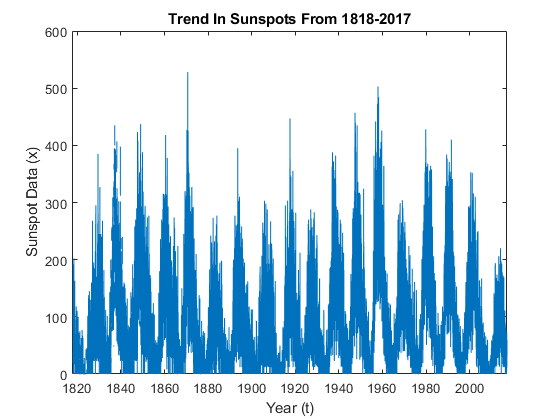

figure(1)
plot(t,x)
title("Trend In Sunspots From 1818-2017")
xlabel("Year (t)")
ylabel("Sunspot Data (x)")
xlim([min(t), max(t)])

### **Observations**

We can see that the larges occurences of sunspots in the dataset occur as peaks in the time-series. These peaks appear *quite* periodically despite the signal being inherently non-stationary. The fairly periodic nature of the signal allows us to gain insights into, perhaps the spectral data of the time-series and, hence, the frequency with which these periodic spikes occur.

### Interpolating Between NaN Data

When performing the FFT, on the time-series, the operation will fail on NaN entries. It is best to interpolate between non-NaN values to produce as much of a 'continuous' time-series as much as possible. We choose to do *nearest-neighbour* interpolation between the sample points since it does not make much sense to have a fraction of a sunspot detected (the ones in the dataset are integer values after all). Furthermore, the number of sunspots should not vary drastically in one day.

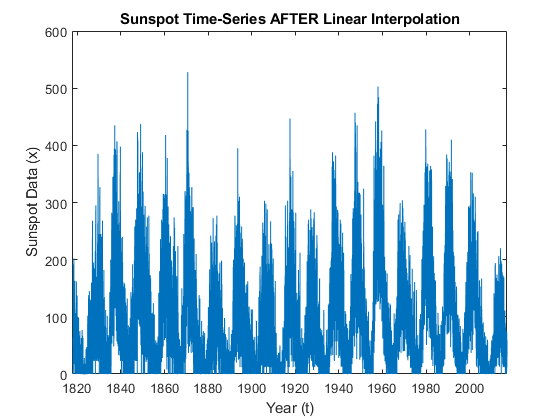

[F,TF] = fillmissing(x, 'nearest', 'SamplePoints', t);
figure(2)
plot(t, F)
title("Sunspot Time-Series AFTER Linear Interpolation")
xlabel("Year (t)")
ylabel("Sunspot Data (x)")
xlim([min(t), max(t)])

## Step 3 - Estimating The Sampling Period

Because of the presence of $-1$ entries in the dataset, this suggests that the sunspot data was sampled at an irregular rate. This is immediately evident from the 17-19 entries with consecutive sunspot recordings and then a relatively longer period of the time of no recorded data until entry 25 where 25 sunspots were recorded.

A simple way would be to take the total length of the $x$-vector and divide this by the number of non-NaN entries in the dataset. This would give us, on average, how many days per sample we have:

total_days = length(t);
actual_samples = length(x(~isnan(x)));
T = total_days / actual_samples

T = 1.0467

The results show that the *average* sample rate is 1.0467 day / sample. This makes sense as the data in the early stages (e.g. 1818 - c.1900s) would be limited due to limited technology. As technology develops, the rate at which we can record sunspots actively would be more efficient. This is true especially for data recorded in more recent times like the 2000s.

## Step 4 - Computing The Frequency Spectrum Of The Data

Given the data is discrete, the DFT is an appropriate method to compute the Frequency Spectrum using the 'fft' MATLAB function. 

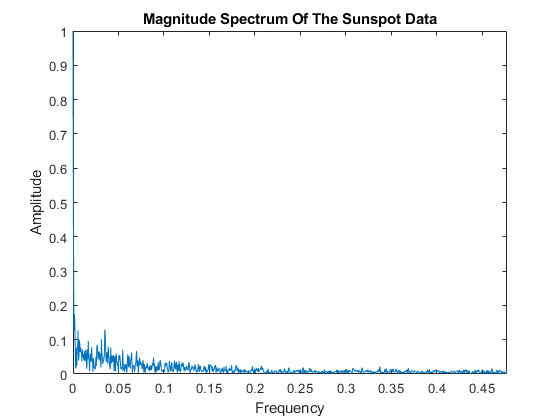

% Take the magnitude of the discrete Fourier Transform of the time-series.
% Use an FFT block size of 1024 samples.
NFFT = 2048;
X = abs(fft(F, NFFT));

% We need to normalise the data in the event of extremely large spikes in
% the resulting spectra:
mag = X / max(X);

% Take the only the positive half of the spectrum (one-sided). Take this
% from index 1 to the last which is the index corresponding to HALF of the
% FFT block size (i.e. index 512)
mag = mag(1:NFFT/2);

% The sampling frequency is the inverse of T. The nyquist frequency is HALF
% of the sampling frequency. This means the frequency axis will terminate
% at Fs/2 ~= 0.5 samples/day
Fs = 1/T;
F_nyq = Fs / 2;

% Generate the frequency bins from 0 to NFFT/2 - 1. These bins are then
% normalised from 0 to 1 by dividing by the FFT block size. Will need to
% multiply by two since we are taking a single-sided spectrum.
freq_bins = 2 * (0:NFFT/2-1) / NFFT;

% The last element of the 'freq_bins' needs to be the Nyquist frequency.
% Multiply freq_bins by F_nyq:
freq_Hz = F_nyq * freq_bins;

% Plot the spectrum:
figure(3)
plot(freq_Hz, mag)
ylabel("Amplitude")
xlabel("Frequency")
title("Magnitude Spectrum Of The Sunspot Data")
xlim([0, max(freq_Hz)])

What we have is a large DC spike in the magnitude spectrum which suggests the presence of the DC offset in the data. We can immediately suggest that this is due to the oscillatory behaviour about a non-zero number of sunspots. This is due to the oscillation being centred about the **average** number of sunspots which we can compute easily.

average_sunspots = mean(F)

average_sunspots = 84.7306

The output shows the data oscillating about the mean value of 84.7412 sunspots. The following plot shows the mean number of sunspots against the time-series graph:

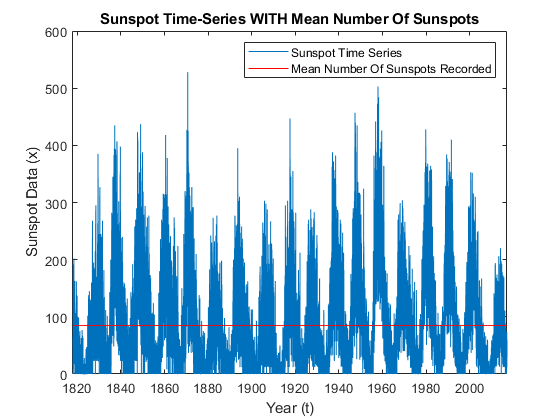

figure(4)
plot(t,F)
hold on
hline = refline(0,average_sunspots);
hline.Color = 'r';
legend("Sunspot Time Series", "Mean Number Of Sunspots Recorded")
title("Sunspot Time-Series WITH Mean Number Of Sunspots")
xlabel("Year (t)")
ylabel("Sunspot Data (x)")
xlim([min(t), max(t)])

There is also a noticeble peak at a frequency of f = 0.03499 Hz (samples/day). The amplitude spectrum tapers off from this point onwards.

## Step 5 - Variation In The Amplitude Spectra In 40 Year Spans

We can use the *Short-Time Fourier Transform *(STFT) to compute the amplitudes in contiguous partial blocks of the signal with overlap between these blocks. We can observe this variation per 40 year chunks. To first do this, we need the unique years in the dataset. We should also convert the current time vector to int16 values.

unique_years = int16(unique(years));
t = int16(t);

We now need to divide the unique_years vector into 40 year chunks:

t_unique_chunk1 = unique_years(1:40);
t_unique_chunk2 = unique_years(41:80);
t_unique_chunk3 = unique_years(81:120);
t_unique_chunk4 = unique_years(121:160);
t_unique_chunk5 = unique_years(161:200);

The last step is to pull the relevant indices based on each unique 40 year chunk from the $t$ vector and and interpolated $x$ vector, $F$. We do that in the following bit of code.

% Extract the first 40 year chunk from time-vector and the data vector.
t_chunk1 = t(ismember(t, t_unique_chunk1, 'rows'));
x_chunk1 = F(ismember(t, t_unique_chunk1, 'rows'));

% Do the same for all chunks to be analysed.
t_chunk2 = t(ismember(t, t_unique_chunk2, 'rows'));
x_chunk2 = F(ismember(t, t_unique_chunk2, 'rows'));

t_chunk3 = t(ismember(t, t_unique_chunk3, 'rows'));
x_chunk3 = F(ismember(t, t_unique_chunk3, 'rows'));

t_chunk4 = t(ismember(t, t_unique_chunk4, 'rows'));
x_chunk4 = F(ismember(t, t_unique_chunk4, 'rows'));

t_chunk5 = t(ismember(t, t_unique_chunk5, 'rows'));
x_chunk5 = F(ismember(t, t_unique_chunk5, 'rows'));


We can now perform the FFT for all $x\_{\mathrm{chunk}}_{i\;}$ for $i=1,2,3,4,5$. The resultant FFT's will be plotted one below the other as subplots in order to clearly see how any of the frequency modes change over these 40 year spans.

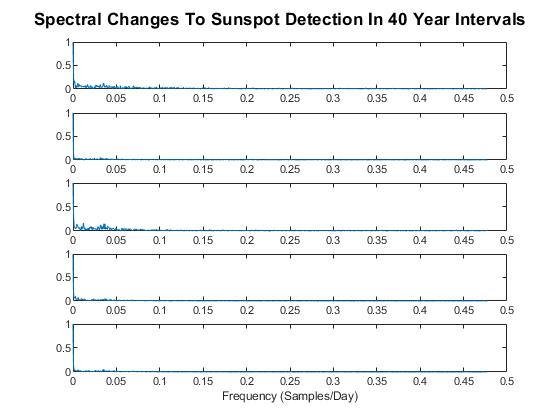

% FFT Block Size
NFFT = 2048;

% Compute the FFT for all chunks and take the magnitude.
X1 = abs(fft(x_chunk1, NFFT));
X2 = abs(fft(x_chunk2, NFFT));
X3 = abs(fft(x_chunk3, NFFT));
X4 = abs(fft(x_chunk4, NFFT));
X5 = abs(fft(x_chunk5, NFFT));

% We need to normalise the data in the event of extremely large spikes in
% the resulting spectra:
X1 = X1 / max(X1);
X2 = X2 / max(X2);
X3 = X3 / max(X3);
X4 = X4 / max(X4);
X5 = X5 / max(X5);

% Take the only the positive half of the spectrum (one-sided). Take this
% from index 1 to the last which is the index corresponding to HALF of the
% FFT block size (i.e. index 512)
X1 = X1(1:NFFT/2);
X2 = X2(1:NFFT/2);
X3 = X3(1:NFFT/2);
X4 = X4(1:NFFT/2);
X5 = X5(1:NFFT/2);

% We can now plot each spectra as individual subplots on a single figure.
% Prepare 5 subplots for each contiguous block of data:
figure(5)
subplot(5,1,1)
plot(freq_Hz, X1)
subplot(5,1,2)
plot(freq_Hz, X2)
subplot(5,1,3)
plot(freq_Hz, X3)
subplot(5,1,4)
plot(freq_Hz, X4)
subplot(5,1,5)
plot(freq_Hz, X5)
sgtitle("Spectral Changes To Sunspot Detection In 40 Year Intervals", 'fontweight', 'bold')
xlabel("Frequency (Samples/Day)")